## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

Set the initial point `x0` and scale `a` for the optimization.

x0 = [2;1];
a = 0;

**Place the **`x0`** value and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

This task has objective and nonlinear constraint functions included. To change these functions, edit the function listings below the task.

To change the constraints, select appropriate constraint types and enter values in the input boxes. You might need to enter values in the section containing `x0` above, and run the section to put values in the workspace.

Run the task by clicking the striped bar to the left, or by choosing **Run** or **Section > Run Section**, or by pressing `Control+Enter`.


Diagnostic information:
Fitness function: @(x)objectiveFcn(x,a)
Nonlinear constraint function: @constraintFcn
2 Variable(s)
6 Nonlinear inequality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationgaussian
Display:           'diagnose'
PlotFcns:          {  'gaplotstopping' 'gaplotbestf' }
End of diagnostic information.

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    1           2512      -15351.3     0.004471      0
    2           6043      -16531.9            0      0
    3           8493      -16531.9            0      1
    4          12870      -16538.2            0      0
Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


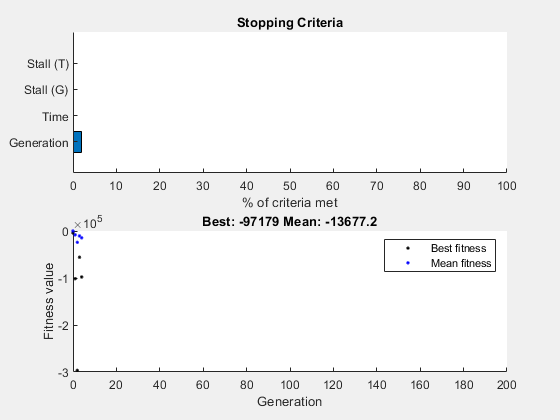

% Pass fixed parameters to objfun
objfun4 = @(x)objectiveFcn(x,a);

% Set nondefault solver options
options4 = optimoptions("ga","Display","diagnose","PlotFcn",["gaplotstopping",...
    "gaplotbestf"]);

% Solve
[solution,objectiveValue] = ga(objfun4,l,[],[],[],[],[],[],@constraintFcn,[],...
    options4);


% Clear variables
clearvars objfun4 options4

## Results

`Optimize` saves the solution to the workspace variable `solution`, and saves the objective function value at the solution to the workspace variable `objectiveValue`. You can see and modify these variable names at the top of the `Optimize` task.

View these variables.

solution

solution =     0.4731    0.4510


objectiveValue

objectiveValue = -1.4504

View the nonlinear constraint function values at the solution.

[ccons,ceqcons] = constraintFcn(solution)

ccons =    -4.5727    2.5727



ceqcons =

     []



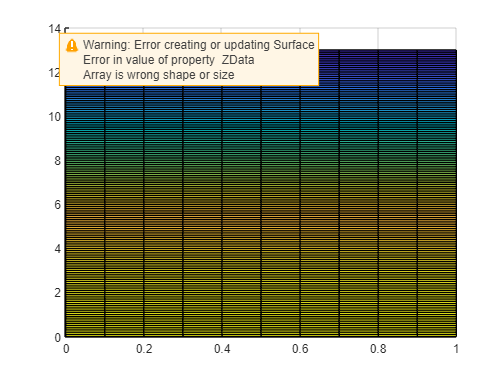

figure
[x, y] = meshgrid(0:0.1:1, 0:0.1:13);
f = 100.*(x.^2 - y.^2) + (1 - x).^2;
surface(x, y, f);
grid on;

% function f = objectiveFcn(x, a)
%     f = 8.*x - 16 - 12.*nthroot((x+4).^2, 3);
% end

% function z = objectiveFcn(x, a)
%     z = -(exp(-x(1).^2 - x(2).^2) + sin(x(1) + x(2)));
% end



function z = objectiveFcn(x, a)
    z = 100*(x(1)^2 - x(2)^2) + (1 - x(1))^2;
end

function [c,ceq] = constraintFcn(x)
    c = [x(1) * x(2) + x(1) - x(2) + 1.5; ...
     10 - x(1) * x(2); ...             
     -x(1); ...                         
     x(1) - 1; ...                    
     -x(2); ...                  
     x(2) - 13];                 
    ceq = [];
end


